# GWSC_Lab3

## Stochastic process - 2021/02/24

### Pseudo-random numbers

rng('default')
rand()

ans = 0.8147

rand()

ans = 0.9058

disp('-------- rng seed reset ---------')

-------- rng seed reset ---------


rng('default')
rand()

ans = 0.8147

rand()

ans = 0.9058

### PDF, CDF and Histogram

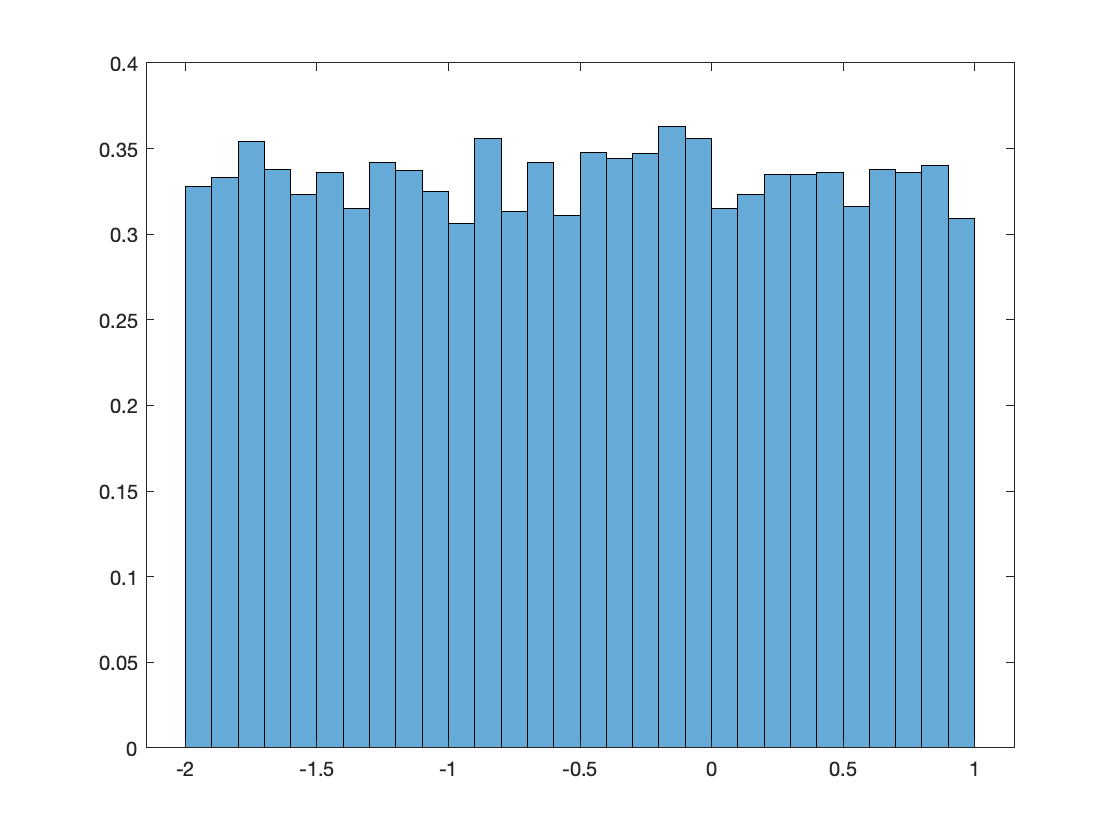


M = 10000; % the estimated probability is getting closer to its true pdf when M gets bigger.
Xvec = customrand(-2,1,[1,M]);
histogram(Xvec,'Normalization',"pdf")

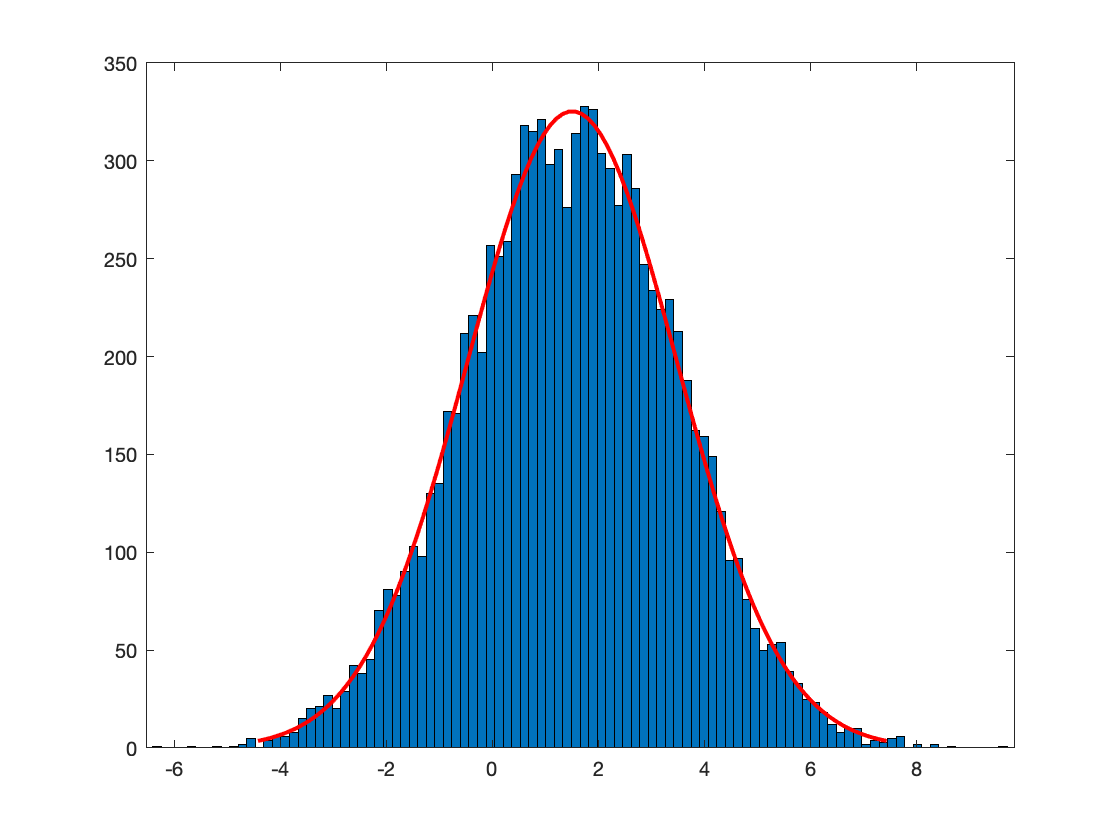

Yvec = customrandn(1.5,2.0,[1,M]);
figure
histfit(Yvec);

pd = fitdist(Yvec','Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 1.50364   [1.46494, 1.54234]
    sigma = 1.97436   [1.94737, 2.00211]


function randomNum = customrand(a,b,n)
% Generate random numbers between [a,b] which has uniform distribution U(0,1)
% CUSTOMRAND(A,B,N)
% A and B are the lower limit and upper limit of the random number, N is
% the dimension of the random number.
% For example, customrand(1,10,[1,10]) generates a 1x10 random number array
% between [1,10].

% QYQ 2021/02/24

randomNum = (b - a) * rand(n) + a;
end

function randomNum = customrandn(a,b,n)
% Generate random numbers which has mean a and variance b^2.
% CUSTOMRANDN(A,B,N)
% A and B is the desired mean and standard deviation of normal
% distribution. N is the dimension of output random number.

randomNum = b * randn(n) + a;
end